Author：黃仕鈞

# Autoregressive Modeling

clear all; clc;

# Initial parameter

## Sampling parameters

$\mathrm{Samples}\;\mathrm{quantity}$, N = 100

N = 100; % quantity of samples

## Gaussian noise


$$e_n \;=\mathrm{randn}\left(N\right)$$


e = randn(N);
e = e / max(e);

# AR(p), Control lag

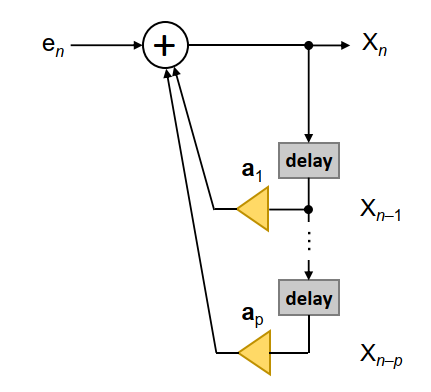


$$X_n =c+\sum_{i=1}^p a_i X_{n-i} +e_n$$


透過改變$a_i$增益來做，AR(1)，表示找前一個採樣 $X_{n-i}$與一個增益$a_i$乘得到結果, delay 1 sampe。

[Autoregressive for forecast error](https://youtu.be/4WWQWeMXvas): Youtube

delay 不能超過sample數量

Only for short-term forecasts

To forcast k-steps ahead($$$\mathrm{F}_{\mathrm{t}+\mathrm{k}}$$$)

Use AR(p) model only if k>p, p  lag p sequence, k is steps

a = [];
sets = 5; % test sets
lag = 10; % Control_lag

% Generate the a(r) AR is not able to linear regression but just test
% time varying a = t/N
for i = 1:N
    a(i) = (i/N); 
end
ac = zeros(sets,1);
ac = [0.1, 0.9, -0.9 ,0.3, 0.5]; % with constant close to 0, 1...

x = zeros(N,sets);
xc = zeros(N,sets); % 初始化矩陣大小 constant

for j =1:lag % lag not calc
    for i = 1:5 % which data
        x(j,i) = 0; % a(i).*x(j,i)+e(j);
        xc(j,i) = 0; % ac(i).*x(j,i)+e(j);
    end
end

for j = 1:sets
    for i = (1+lag):N % calc start from AR(p->lag) --> lag+1
        xc(i,j) = ac(j).*x(i-lag,j)+e(i); % 對照組 constant a
        x(i,j) = a(i).*x(i-lag,j)+e(i);
    end
end

# Plot

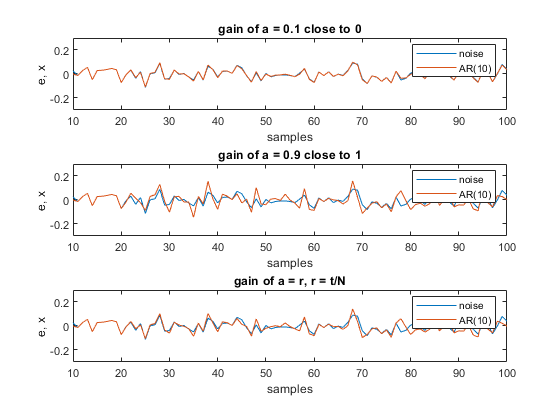

% calc end
str1 = ['AR', '(', string(lag), ')' ];
t = linspace(1,N,N);
ylimit_const = [-0.3, 0.3];
AR = sprintf( str1(1)+str1(2)+str1(3)+str1(4));

figure();
subplot(3, 1, 1);
plot(t(lag:end),e(lag:end));
hold on;
plot(t(lag:end),xc(lag:end,1));
title('gain of a = 0.1 close to 0');
xlim([lag, N]); %xlim(0, N);
ylim(ylimit_const); %ylim(-2, 2);
xlabel('samples');
ylabel('e, x') ;
% legend(['noise', 'AR(2)'], loc='best');
% tight_layout(pad=0.5, w_pad=0.5, h_pad=1.0);
legend('noise', AR)
subplot(3, 1, 2);
plot(t(lag:end),e(lag:end));
hold on;
plot(t(lag:end),xc(lag:end,2));
title('gain of a = 0.9 close to 1')
xlim([lag, N]); %xlim(0, N);
ylim(ylimit_const); %ylim(-2, 2);
xlabel('samples');
ylabel('e, x') ;
% legend(['noise', 'AR(2)'], loc='best');
% tight_layout(pad=0.5, w_pad=0.5, h_pad=1.0);
legend('noise', AR)
subplot(3, 1, 3);
plot(t(lag:end),e(lag:end));
hold on;
plot(t(lag:end),x(lag:end,1));
title('gain of a = r, r = t/N')
xlim([lag, N]); %xlim(0, N);
ylim(ylimit_const); %ylim(-2, 2);
xlabel('samples');
ylabel('e, x') ;
% legend(['noise', 'AR(2)'], loc='best');
% tight_layout(pad=0.5, w_pad=0.5, h_pad=1.0);
legend('noise', AR)

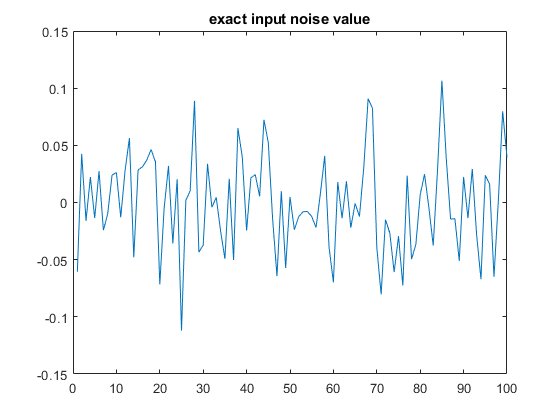

figure(); plot(t,e);title('exact input noise value')